# Refined System Trajectory for Velocity Profile Generation

## Define system parameters

Define reference points

% load data files
load COMTraj.mat

% define reference points
xRef = xCOM; % x-coordinate in m
yRef = yCOM; % y-coordinate in m
refPose = [xRef yRef];

Define system parameters

X_o = xRef(1); % initial system position in x direction
Y_o = yRef(1); % initial system position in y direction
wpts = 60; % set number of waypoints for path interpolation

## Calculate reference position vectors

Based on how far the system travels, the pose is generated using 1-D lookup tables. In addition, the corresponding orientation is also calculated.

% calculate distance vector
distancematrix = squareform(pdist(refPose));
distancesteps = zeros(length(refPose)-1,1);
for i = 2:length(refPose)
    distancesteps(i-1,1) = distancematrix(i,i-1);
end
totalDistance = sum(distancesteps); % Total distance travelled
distbp = cumsum([0; distancesteps]); % Distance for each waypoint
gradbp = linspace(0,totalDistance,wpts); % Linearize distance

% linearize X and Y vectors based on distance
xRef2 = interp1(distbp,xRef,gradbp);
yRef2 = interp1(distbp,yRef,gradbp);
xRef2s = smooth(gradbp,xRef2); % smooth waypoints
yRef2s = smooth(gradbp,yRef2); % smooth waypoints

% calculate theta vector
% theta = orientation angle of the path at reference points
thetaRef = zeros(length(gradbp),1);
for i = 2:length(gradbp)
    thetaRef(i,1) = atan2d((yRef2(i)-yRef2(i-1)),(xRef2(i)-xRef2(i-1)));
end
thetaRefs = smooth(gradbp,thetaRef); % smooth of theta in degree
psi_o = deg2rad(thetaRefs(1)); % initial yaw angle in radians

% save modified trajectory for velocity profile generation
save Data/COM_Trajectory/SysTraj.mat xRef2s yRef2s totalDistance

Plot the figures

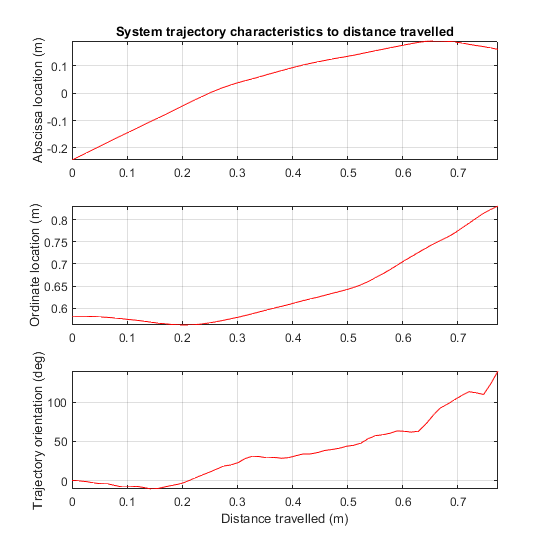

f = figure;
f.Position = [10 10 550 550];

subplot(3,1,1)
plot(gradbp,xRef2s,'r-')
title('System trajectory characteristics to distance travelled')
ylabel('Abscissa location (m)'), grid on, axis tight

subplot(3,1,2)
plot(gradbp,yRef2s,'r-')
ylabel('Ordinate location (m)'), grid on, axis tight

subplot(3,1,3)
plot(gradbp,thetaRefs,'r-')
xlabel('Distance travelled (m)')
ylabel('Trajectory orientation (deg)'), grid on, axis tight

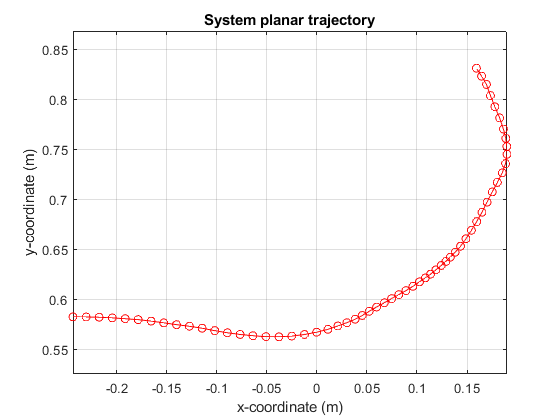

figure
plot(xRef2s,yRef2s,'ro-')
title('System planar trajectory')
xlabel('x-coordinate (m)')
ylabel('y-coordinate (m)')
axis equal, grid on

## Calculate curvature vector

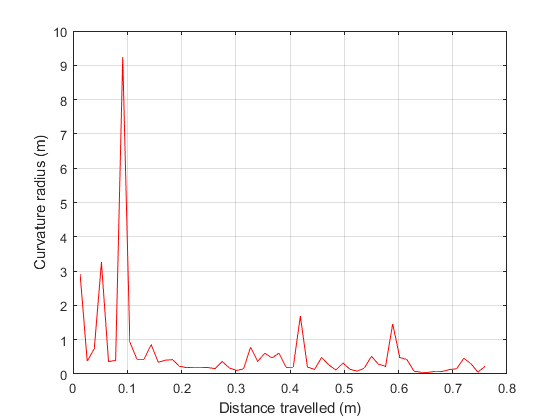

% create direction vector
direction = ones(length(gradbp),1);

% calculate curvature radius
coors_xy = [xRef2s,yRef2s];
[~,curve] = curvature(coors_xy);
figure
plot(gradbp,curve,'r-')
xlabel('Distance travelled (m)')
ylabel('Curvature radius (m)')
grid on